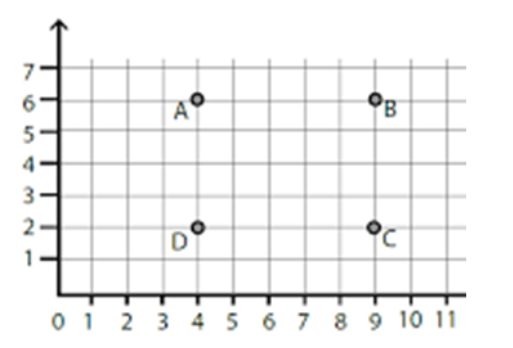

%% EXAMPLE: Differential Drive Path Following
% In this example, a differential drive robot navigates a set of waypoints 
% using the Pure Pursuit algorithm while avoiding obstacles using the
% Vector Field Histogram (VFH) algorithm.
% 
% Copyright 2019 The MathWorks, Inc.

%% Simulation setup
% Define Vehicle
R = 0.1;                        % Wheel radius [m]
L = 0.5;                        % Wheelbase [m]
dd = DifferentialDrive(R,L);

% Sample time and time array
sampleTime = 0.1;              % Sample time [s]
tVec = 0:sampleTime:27;        % Time array

% Initial conditions
initPose = [4;6;0];            % Initial pose (x y theta)
pose = zeros(3,numel(tVec));   % Pose matrix
pose(:,1) = initPose;


% Load map

%complexMap       41x52                2132  logical              
%emptyMap         26x27                 702  logical              
%simpleMap        26x27                 702  logical              
%ternaryMap      501x501            2008008  double  

close all
load exampleMap

% Create lidar sensor
lidar = LidarSensor;
lidar.sensorOffset = [0,0];
lidar.scanAngles = linspace(-pi,pi,200);%51
lidar.maxRange = 5;%5

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;
viz.mapName = 'map';
attachLidarSensor(viz,lidar);

%% Path planning and following

% Create waypoints
waypoints = [initPose(1:2)'; 
             9 6;
             9 2;
             4 6;
             2 4;];

% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.8;%0.5
controller.DesiredLinearVelocity = 1; %0.75
controller.MaxAngularVelocity = 2

controller =   controllerPurePursuit with properties:

                Waypoints: [5×2 double]
       MaxAngularVelocity: 2
        LookaheadDistance: 0.8000
    DesiredLinearVelocity: 1


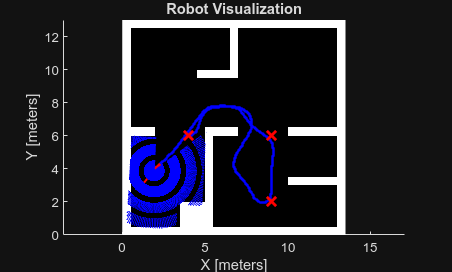


% Vector Field Histogram (VFH) for obstacle avoidance
vfh = controllerVFH;
vfh.DistanceLimits = [0.05 3]; %0.05 3
vfh.NumAngularSectors = 36; %36
vfh.HistogramThresholds = [5 10]; % 5y 10
vfh.RobotRadius = L/2;
vfh.SafetyDistance = 0.2;
vfh.MinTurningRadius = 0.2;%0.25

%% Simulation loop
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    
    % Get the sensor readings
    curPose = pose(:,idx-1);
    ranges = lidar(curPose);
        
    % Run the path following and obstacle avoidance algorithms
    [vRef,wRef,lookAheadPt] = controller(curPose);
    targetDir = wrapToPi(atan2(lookAheadPt(2)-curPose(2), lookAheadPt(1)-curPose(1)) - curPose(3));
    steerDir = vfh(ranges,lidar.scanAngles,targetDir);    
    if ~isnan(steerDir) && abs(steerDir-targetDir) > 0.2
        wRef = 1.0*steerDir;                 % gana proporcional un poco más alta
        vRef = vRef * max(0.2, cos(steerDir)); % frena al girar fuerte
    end
    
    % Control the robot
    velB = [vRef;0;wRef];                   % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,curPose);  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = curPose + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints,ranges)
    waitfor(r);
end

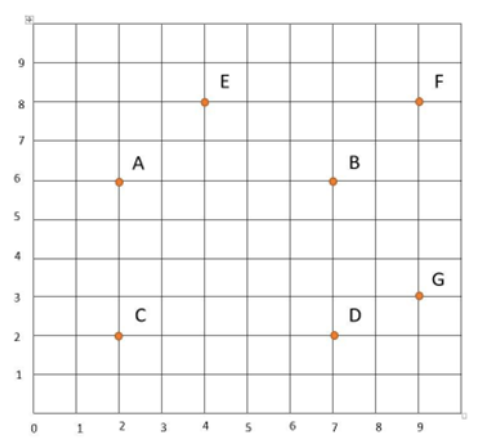

%% EXAMPLE: Differential Drive Path Following
% In this example, a differential drive robot navigates a set of waypoints 
% using the Pure Pursuit algorithm while avoiding obstacles using the
% Vector Field Histogram (VFH) algorithm.
% 
% Copyright 2019 The MathWorks, Inc.

%% Simulation setup
% Define Vehicle
R = 0.1;                        % Wheel radius [m]
L = 0.5;                        % Wheelbase [m]
dd = DifferentialDrive(R,L);

% Sample time and time array
sampleTime = 0.1;              % Sample time [s]
tVec = 0:sampleTime:24;        % Time array

% Initial conditions
initPose = [2;2;0];            % Initial pose (x y theta)
pose = zeros(3,numel(tVec));   % Pose matrix
pose(:,1) = initPose;


% Load map

%complexMap       41x52                2132  logical              
%emptyMap         26x27                 702  logical              
%simpleMap        26x27                 702  logical              
%ternaryMap      501x501            2008008  double  

close all
load exampleMap

% Create lidar sensor
lidar = LidarSensor;
lidar.sensorOffset = [0,0];
lidar.scanAngles = linspace(-pi,pi,200);%51
lidar.maxRange = 1;%5

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;
viz.mapName = 'map';
attachLidarSensor(viz,lidar);

%% Path planning and following

% Create waypoints
waypoints = [initPose(1:2)'; 
             2 6;
             4 8;
             7 6;
             7 2;
             9 3;
             9 8;
             ];

% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.8;%0.5
controller.DesiredLinearVelocity = 1; %0.75
controller.MaxAngularVelocity = 2

controller =   controllerPurePursuit with properties:

                Waypoints: [7×2 double]
       MaxAngularVelocity: 2
        LookaheadDistance: 0.8000
    DesiredLinearVelocity: 1


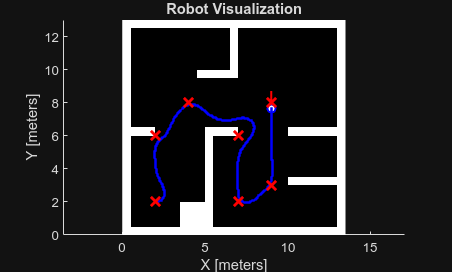


% Vector Field Histogram (VFH) for obstacle avoidance
vfh = controllerVFH;
vfh.DistanceLimits = [0.05 3]; %0.05 3
vfh.NumAngularSectors = 36; %36
vfh.HistogramThresholds = [5 10]; % 5y 10
vfh.RobotRadius = L/2;
vfh.SafetyDistance = 0.2;
vfh.MinTurningRadius = 0.2;%0.25

%% Simulation loop
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    
    % Get the sensor readings
    curPose = pose(:,idx-1);
    ranges = lidar(curPose);
        
    % Run the path following and obstacle avoidance algorithms
    [vRef,wRef,lookAheadPt] = controller(curPose);
    targetDir = wrapToPi(atan2(lookAheadPt(2)-curPose(2), lookAheadPt(1)-curPose(1)) - curPose(3));
    steerDir = vfh(ranges,lidar.scanAngles,targetDir);    
    if ~isnan(steerDir) && abs(steerDir-targetDir) > 0.2
        wRef = 1.0*steerDir;                 % gana proporcional un poco más alta
        vRef = vRef * max(0.2, cos(steerDir)); % frena al girar fuerte
    end
    
    % Control the robot
    velB = [vRef;0;wRef];                   % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,curPose);  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = curPose + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints,ranges)
    waitfor(r);
end

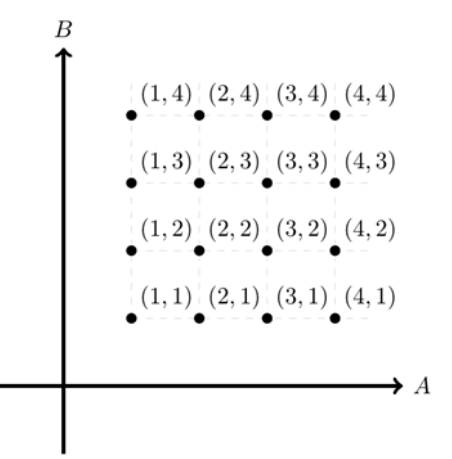

%% EXAMPLE: Differential Drive Path Following
% In this example, a differential drive robot navigates a set of waypoints 
% using the Pure Pursuit algorithm while avoiding obstacles using the
% Vector Field Histogram (VFH) algorithm.
% 
% Copyright 2019 The MathWorks, Inc.

%% Simulation setup
% Define Vehicle
R = 0.1;                        % Wheel radius [m]
L = 0.5;                        % Wheelbase [m]
dd = DifferentialDrive(R,L);

% Sample time and time array
sampleTime = 0.1;              % Sample time [s]
tVec = 0:sampleTime:74;        % Time array

% Initial conditions
initPose = [3;3;0];            % Initial pose (x y theta)
pose = zeros(3,numel(tVec));   % Pose matrix
pose(:,1) = initPose;


% Load map

%complexMap       41x52                2132  logical              
%emptyMap         26x27                 702  logical              
%simpleMap        26x27                 702  logical              
%ternaryMap      501x501            2008008  double  

close all
load exampleMap

% Create lidar sensor
lidar = LidarSensor;
lidar.sensorOffset = [0,0];
lidar.scanAngles = linspace(-pi,pi,200);%51
lidar.maxRange = 2;%5

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;
viz.mapName = 'map';
attachLidarSensor(viz,lidar);

%% Path planning and following

% Create waypoints
waypoints = [initPose(1:2)'; 
             3 6;
             3 9;
             3 12;
             6 12;
             6 8;
             6 5;
             6 2;
             9 2;
             9 6;
             9 8;
             9 12;
             12 12;
             12 8;
             12 4;
             12 2;
             ];

% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.8;%0.5
controller.DesiredLinearVelocity = 1; %0.75
controller.MaxAngularVelocity = 2

controller =   controllerPurePursuit with properties:

                Waypoints: [16×2 double]
       MaxAngularVelocity: 2
        LookaheadDistance: 0.8000
    DesiredLinearVelocity: 1


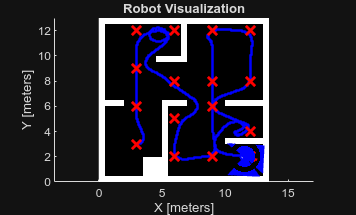


% Vector Field Histogram (VFH) for obswtacle avoidance
vfh = controllerVFH;
vfh.DistanceLimits = [0.05 3]; %0.05 3
vfh.NumAngularSectors = 36; %36
vfh.HistogramThresholds = [5 10]; % 5y 10 
vfh.RobotRadius = L/2;
vfh.SafetyDistance = 0.05;
vfh.MinTurningRadius = 0.02;%0.25

%% Simulation loop
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    
    % Get the sensor readings
    curPose = pose(:,idx-1);
    ranges = lidar(curPose);
        
    % Run the path following and obstacle avoidance algorithms
    [vRef,wRef,lookAheadPt] = controller(curPose);
    targetDir = wrapToPi(atan2(lookAheadPt(2)-curPose(2), lookAheadPt(1)-curPose(1)) - curPose(3));
    steerDir = vfh(ranges,lidar.scanAngles,targetDir);    
    if ~isnan(steerDir) && abs(steerDir-targetDir) > 0.2
        wRef = 1.0*steerDir;                 % gana proporcional un poco más alta
        vRef = vRef * max(0.2, cos(steerDir)); % frena al girar fuerte
    end
    
    % Control the robot
    velB = [vRef;0;wRef];                   % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,curPose);  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = curPose + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints,ranges)
    waitfor(r);
end

**Conclusiones:**

A lo largo de esta actividad se implementó un esquema de navegación local que combina Pure Pursuit para el seguimiento de waypoints y Vector Field Histogram (VFH) para la evasión reactiva de obstáculos, aplicándolo a tres escenarios de complejidad creciente sobre un robot diferencial. La comparación entre los ejercicios mostró que ambos algoritmos resuelven problemas distintos, seguimiento global y evasión local, y que su correcta coordinación, junto con un ajuste cuidadoso de parámetros como `LookaheadDistance`, `MaxAngularVelocity`, `SafetyDistance` y el alcance del lidar, es lo que determina la calidad del comportamiento final al evadir las paredes del mapa.

La principal limitación observada fue el aclance de los puntos cerca de las paredes, donde el VFH, al ser reactivo, no puede alcanzar el punto correctamente en algunas ocasiones. Esto evidenció que el esquema funciona bien cuando los waypoints se diseñan respetando la topología del mapa. De manera final aprendí que, los ejercicios confirmaron que una navegación robusta no depende de un solo algoritmo, sino del balance entre planeación, seguimiento y evasión.

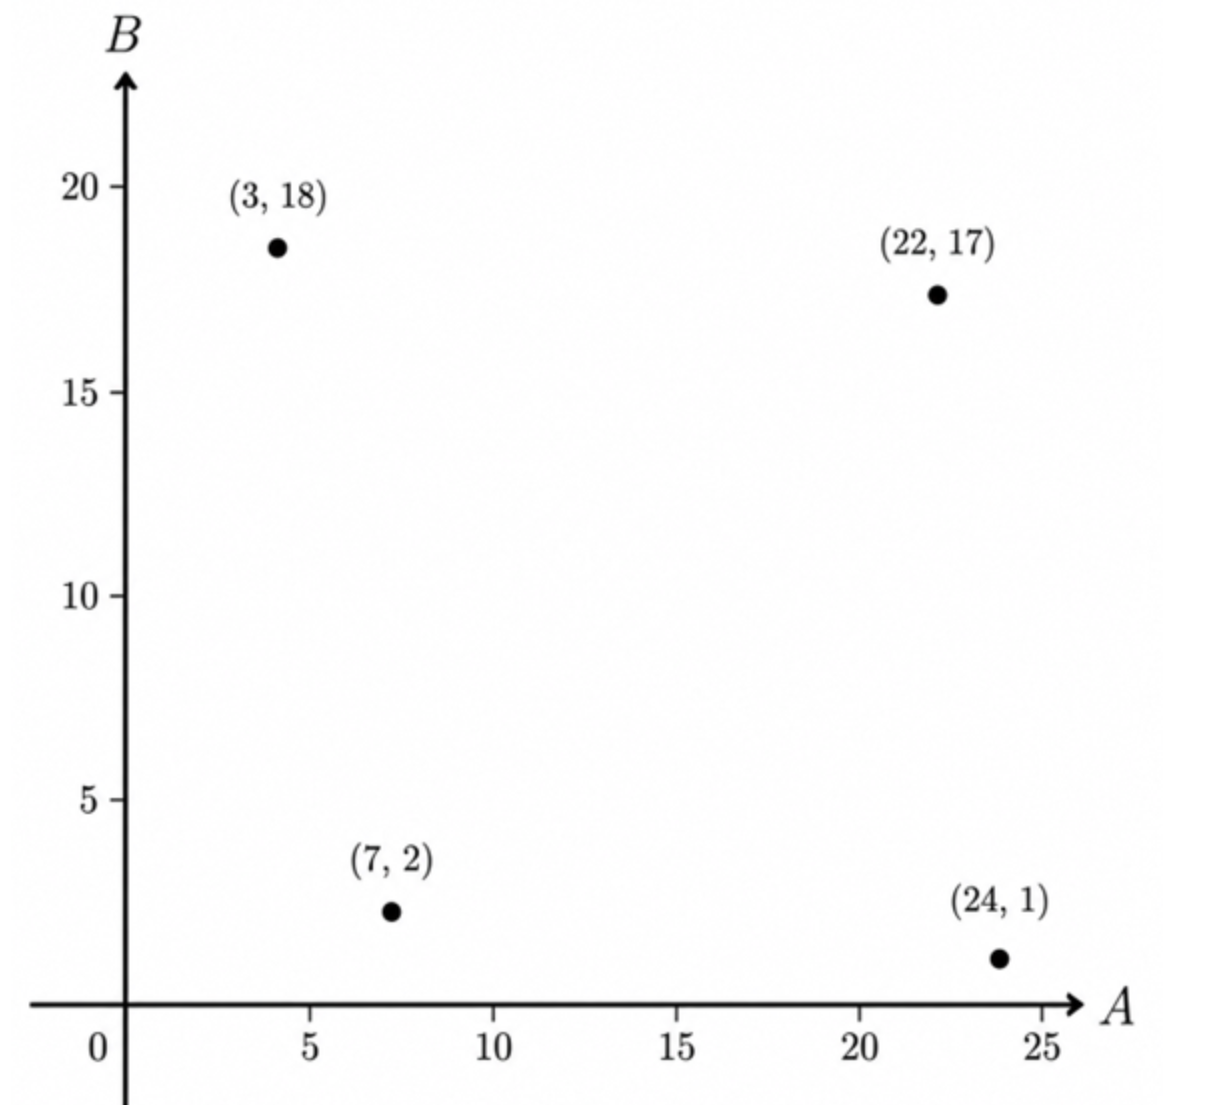

%% EXAMPLE: Differential Drive Path Following
% In this example, a differential drive robot navigates a set of waypoints 
% using the Pure Pursuit algorithm while avoiding obstacles using the
% Vector Field Histogram (VFH) algorithm.
% 
% Copyright 2019 The MathWorks, Inc.

%% Simulation setup
% Define Vehicle
R = 0.1;                        % Wheel radius [m]
L = 0.5;                        % Wheelbase [m]
dd = DifferentialDrive(R,L);

% Sample time and time array
sampleTime = 0.1;              % Sample time [s]
tVec = 0:sampleTime:133;        % Time array

% Initial conditions
initPose = [7;2;0];            % Initial pose (x y theta)
pose = zeros(3,numel(tVec));   % Pose matrix
pose(:,1) = initPose;


% Load map

%complexMap       41x52                2132  logical              
%emptyMap         26x27                 702  logical              
%simpleMap        26x27                 702  logical              
%ternaryMap      501x501            2008008  double  

close all
load complexMap

% Create lidar sensor
lidar = LidarSensor;
lidar.sensorOffset = [0,0];
lidar.scanAngles = linspace(-pi,pi,200);%51
lidar.maxRange = 2;%5

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;
viz.mapName = 'map';
attachLidarSensor(viz,lidar);

%% Path planning and following

% Create waypoints
waypoints = [initPose(1:2)'; 
             3 18;
             15 15;
             22 17;
              24 9;
              17 8;
             24 1];

% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.6;%0.5
controller.DesiredLinearVelocity = 1; %0.75
controller.MaxAngularVelocity = 2

controller =   controllerPurePursuit with properties:

                Waypoints: [7×2 double]
       MaxAngularVelocity: 2
        LookaheadDistance: 0.6000
    DesiredLinearVelocity: 1


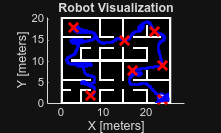


% Vector Field Histogram (VFH) for obstacle avoidance
vfh = controllerVFH;
vfh.DistanceLimits = [0.05 3]; %0.05 3
vfh.NumAngularSectors = 36; %36
vfh.HistogramThresholds = [5 10]; % 5y 10
vfh.RobotRadius = L/2;
vfh.SafetyDistance = 0.1;
vfh.MinTurningRadius = 0.1;%0.25

%% Simulation loop
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    
    % Get the sensor readings
    curPose = pose(:,idx-1);
    ranges = lidar(curPose);
        
    % Run the path following and obstacle avoidance algorithms
    [vRef,wRef,lookAheadPt] = controller(curPose);
    targetDir = wrapToPi(atan2(lookAheadPt(2)-curPose(2), lookAheadPt(1)-curPose(1)) - curPose(3));
    steerDir = vfh(ranges,lidar.scanAngles,targetDir);    
    if ~isnan(steerDir) && abs(steerDir-targetDir) > 0.2
        wRef = 1.0*steerDir;                 % gana proporcional un poco más alta
        vRef = vRef * max(0.2, cos(steerDir)); % frena al girar fuerte
    end
    
    % Control the robot
    velB = [vRef;0;wRef];                   % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,curPose);  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = curPose + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints,ranges)
    waitfor(r);
end

En este último ejercicio se aplicó el mismo esquema Pure Pursuit + VFH sobre el `complexMap`, un entorno significativamente más complejo que los anteriores, con múltiples corredores estrechos, La mayor densidad de paredes obligó a que el robot operara casi todo el tiempo en modo reactivo: el VFH dominaba sobre el seguimiento del Pure Pursuit en gran parte del recorrido, ya que los waypoints rara vez resultaban directamente alcanzables en línea recta. Para hacer viable la navegación fue necesario ajustar los parámetros a un perfil más conservador y preciso —`LookaheadDistance = 0.6`, `SafetyDistance = 0.1`, `MinTurningRadius = 0.1` y un alcance de lidar más corto (2 m)— de modo que el robot reaccionara con mayor finura en los pasillos.

El principal aprendizaje fue que, ante un mapa complejo, el diseño manual de waypoints se vuelve indispensable: hubo que añadir puntos intermedios para descomponer el problema global en tramos que el VFH sí pudiera resolver localmente.